# Feedforward neural network

BE CAREFUL, THIS SCRIPT CAN OVERWRITE FILES

buffer_train = struct with fields:
    X: [14×10000 double]
    Y: [3×10000 double]

buffer_validation = struct with fields:
    X: [14×1000 double]
    Y: [3×1000 double]

Nsamples = 11000

Ninputs = 14

Noutputs = 3

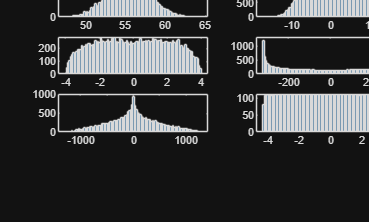

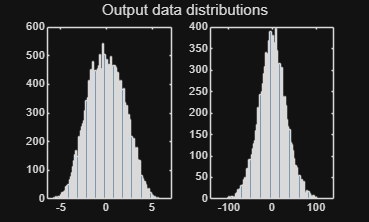

ans = 280.6347

ie_max = 6.4251

ix_max = 4.2960

iy_max = 4

is_max = 8.5000

vo_max = 223.0806

vB_max = 446.1612

VCdiff = 0.1000

eta = 1.4416

Xmax = 1.0e+03 *

    0.0553
    0.0116
    0.0116
    0.0116
    0.0116
    0.0116
    0.0116
    0.0040
    0.0040
    0.3224
    0.3224
    1.2898
    1.2898
    0.0043


Ymax =     8.5000
    8.5000
  223.0806


ans =           14       11000


ans =            3       11000


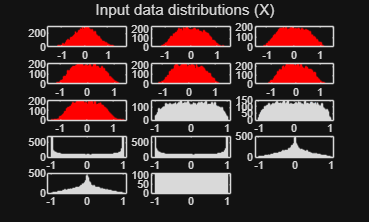

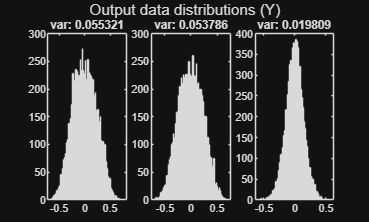

run('DataPreparation.mlx');

Weight averaging

history = load('ImitationLearning\ActualArchitecture\Results_v2.mat').history;
[~, sorted_idxs] = sort([history.val_loss], 'ascend');
sorted_history = history(sorted_idxs)

sorted_history = 1×6 struct array with fields:
    net
    train_loss
    val_loss

% net = sorted_history(1).net;

M = min(3, numel(sorted_history));
nets = cell(1, M);
for k = 1:M
    nets{k} = sorted_history(k).net;
end
net_avg = nets{1};
tbl     = net_avg.Learnables;
nParams = size(tbl, 1);
for i = 1:nParams
    vals = cellfun(@(n) n.Learnables.Value{i}, nets, 'UniformOutput', false);
    nd = ndims(vals{1});
    stacked = cat(nd+1, vals{:});
    avgVal  = mean(stacked, nd+1);
    net_avg.Learnables.Value{i} = avgVal;
end
net = net_avg;

% net = load('ImitationLearning\ActualArchitecture\Results_v2.mat').net;


Quantization

% 1) Crear el cuantizador en entorno MATLAB
quantObj = dlquantizer(net, 'ExecutionEnvironment','MATLAB');

% 2) Calibrar con tu dsX_tr
nBatches    = min(100, numel(dsX_tr));
calibration = subset(dsX_tr, 1:nBatches);
calibrate(quantObj, calibration, 'MiniBatchSize', 64);

% 3) Cuantizar la red
qNet = quantize(quantObj);

Error using dlquantizer/quantize (line 70)
Unable to resolve the name 'fixed.internal.type.can2DMatrixMulOverflow'.


% 4) (Opcional) Validar degradación
Yq = predict(qNet, dlX_val);
Yo = predict(net,  dlX_val);
fprintf('MSE cuantizado vs original: %g\n', mse(extractdata(Yq), extractdata(Yo)));

% 5) Guardar
save('ImitationLearning/ActualArchitecture/Net_Quantized.mat','qNet');




## Architecture

% argsFFNN                  = struct();
% argsFFNN.Ninputs          = Ninputs;
% argsFFNN.Noutputs         = Noutputs;
% % argsFFNN.Nlayers          = 1;
% % argsFFNN.Nneurons         = 5*Ninputs;
% argsFFNN.Nlayers          = 1;
% argsFFNN.Nneurons         = 5*Ninputs;
% argsFFNN.HiddenActivation = 'relu'; % relu, tanh, sigmoid
% argsFFNN.OutputActivation = 'tanh';
% argsFFNN.Dropout          = 0;
% argsFFNN.WinitFcn         = 'glorot';
% argsFFNN.BinitFcn         = 'glorot';
% argsFFNN.BatchNorm        = true;
% argsFFNN.TrainBias        = true;
% 
% net = FFNNgenerator(argsFFNN)
% 
% summary(net)

## Training

output_variance = var(extractdata(dlY_tr), 0, 2);
var_e = mean(output_variance(1:n));
var_o = output_variance(end);
ErrorWeights = [ones(n, 1); var_e/var_o]

ErrorWeights =     1.0000
    1.0000
    2.7657



argsFFNNtrain                    = struct();
argsFFNNtrain.net                = net;
argsFFNNtrain.X_tr               = dlX_tr;
argsFFNNtrain.Y_tr               = dlY_tr;
argsFFNNtrain.dsXY_tr            = dsXY_tr;
argsFFNNtrain.X_val              = dlX_val;
argsFFNNtrain.Y_val              = dlY_val;
argsFFNNtrain.Plots              = 'training-progress'

argsFFNNtrain = struct with fields:
        net: [1×1 dlnetwork]
       X_tr: [14×10000 dlarray]
       Y_tr: [3×10000 dlarray]
    dsXY_tr: [1×1 matlab.io.datastore.CombinedDatastore]
      X_val: [14×1000 dlarray]
      Y_val: [3×1000 dlarray]
      Plots: 'training-progress'

argsFFNNtrain.Verbose            = false;
argsFFNNtrain.HuberThreshold     = 1;
argsFFNNtrain.ErrorWeights       = ErrorWeights;
argsFFNNtrain.LearnRateScheduler = "cyclic"; % test, exponential, cyclic, super-convergence
argsFFNNtrain.InitialLearnRate   = 1e-2;
argsFFNNtrain.FinalLearnRate     = 1e-5;
argsFFNNtrain.MinLearnRate       = 1e-5;
argsFFNNtrain.MaxLearnRate       = 1e-2;
% argsFFNNtrain.MaxEpochs          = 200;
% argsFFNNtrain.MiniBatchSize      = 512;
% argsFFNNtrain.ValidationPatience = 200;
% argsFFNNtrain.MaxEpochs          = 200;
% argsFFNNtrain.MiniBatchSize      = 128;
% argsFFNNtrain.ValidationPatience = 200;
% argsFFNNtrain.MaxEpochs          = 200;
% argsFFNNtrain.MiniBatchSize      = 256;
% argsFFNNtrain.ValidationPatience = 200;
% argsFFNNtrain.MaxEpochs          = 500;
% argsFFNNtrain.MiniBatchSize      = 1024;
% argsFFNNtrain.ValidationPatience = 500;
% argsFFNNtrain.MaxEpochs          = 1000;
% argsFFNNtrain.MiniBatchSize      = 64;
% argsFFNNtrain.ValidationPatience = 1000;
argsFFNNtrain.MaxEpochs          = 50;
argsFFNNtrain.MiniBatchSize      = 64;
argsFFNNtrain.ValidationPatience = 50;

% [net, history] = FFNNtrain(argsFFNNtrain, 'custom')
% 
% save('ImitationLearning\ActualArchitecture\Results10k_v2.mat', 'net', 'history');

[~, ~, state]= dlfeval(@FFNNLoss, net, dlX_tr, dlY_tr, 'train', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights);
net.State = state;

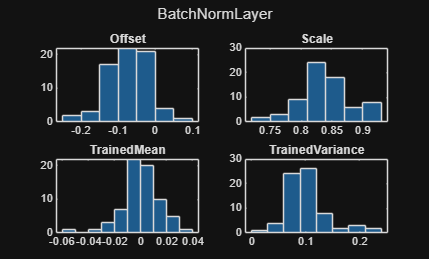

figure
subplot(2, 2, 1)
histogram(net.Layers(3).Offset)
title('Offset')
subplot(2, 2, 2)
histogram(net.Layers(3).Scale)
title('Scale')
subplot(2, 2, 3)
histogram(net.Layers(3).TrainedMean)
title('TrainedMean')
subplot(2, 2, 4)
histogram(net.Layers(3).TrainedVariance)
title('TrainedVariance')
sgtitle('BatchNormLayer')

## Summary

trainPerformance = dlfeval(@FFNNLoss, net, dlX_tr, dlY_tr, 'validation', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights);
valPerformance   = dlfeval(@FFNNLoss, net, dlX_val, dlY_val, 'validation', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights);

disp(['Rendimiento en el conjunto de entrenamiento: ', num2str(trainPerformance)]);

Rendimiento en el conjunto de entrenamiento: 0.0051079


disp(['Rendimiento en el conjunto de validación: ', num2str(valPerformance)]);

Rendimiento en el conjunto de validación: 0.0054577


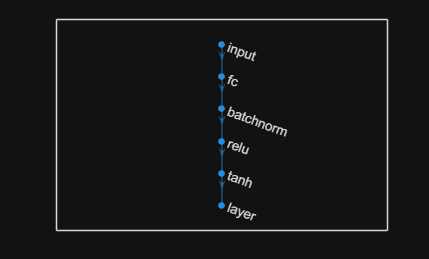


figure
plot(net)

analyzeNetwork(net);
summary(net)

   Initialized: true
   Number of learnables: 1.4k
   Inputs:
      1   'input'   14 features


# Performance analysis

## Error histogram

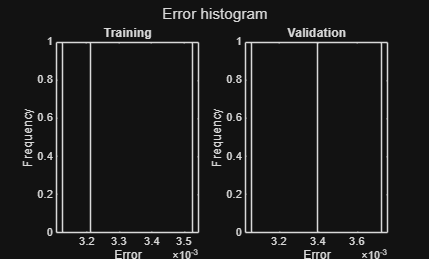

Y_tr_pred = extractdata(net.predict(dlX_tr));
Y_val_pred = extractdata(net.predict(dlX_val));

figure
subplot(1, 2, 1)
histogram(mean((Y_tr_pred - Y_tr).^2, 2), 1000)
title("Training")
xlabel("Error");
ylabel("Frequency")

subplot(1, 2, 2)
histogram(mean((Y_val_pred - Y_val).^2, 2), 1000)
title("Validation")
xlabel("Error");
ylabel("Frequency")

sgtitle('Error histogram');

## Regression

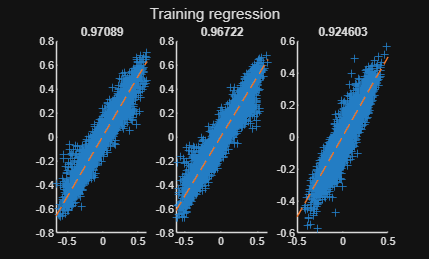

% xlabel("Predicted")
% ylabel("Actual")
% title("Correlation")

figure
title("Training")
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_tr_pred(1, :), Y_tr(1, :), "+")
title(corr(Y_tr_pred(1, :)', Y_tr(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_tr_pred(idx, :), Y_tr(idx, :), "+")
    title(corr(Y_tr_pred(idx, :)', Y_tr(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Training regression');

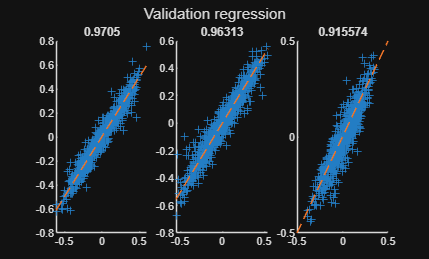


figure
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_val_pred(1, :), Y_val(1, :), "+")
title(corr(Y_val_pred(1, :)', Y_val(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_val_pred(idx, :), Y_val(idx, :), "+")
    title(corr(Y_val_pred(idx, :)', Y_val(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Validation regression');

## Weight matrix analysis

Learnables = net.Learnables

Learnables = 6×3 table
       Layer       Parameter         Value     
    ___________    _________    _______________
    "fc"           "Weights"    {70×14 dlarray}
    "fc"           "Bias"       {70×1  dlarray}
    "batchnorm"    "Offset"     {70×1  dlarray}
    "batchnorm"    "Scale"      {70×1  dlarray}
    "tanh"         "Weights"    { 3×70 dlarray}
    "tanh"         "Bias"       { 3×1  dlarray}

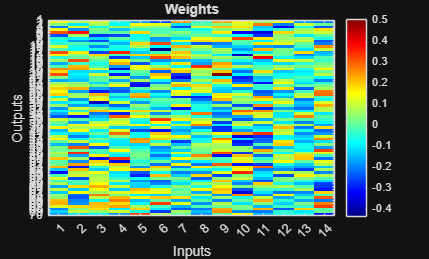

Learnables = Learnables.Value;

weights_input_hidden = extractdata(Learnables{1});

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Weights');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));

Near zero weights

weights_treshold = 0.01 * max(abs(weights_input_hidden(:)))

weights_treshold = single
0.0051

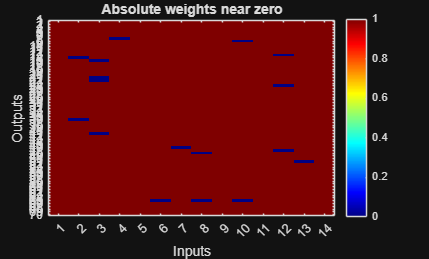

weights_input_hidden(abs(weights_input_hidden) <= weights_treshold) = 0;
weights_input_hidden(abs(weights_input_hidden) > weights_treshold) = 1;

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Absolute weights near zero');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));